clc;
clear all;

A = [0 1 0; 244.86 -0.094 -26.29; 0 0 -250];
B = [0;0;5];
C = [1 0 0];
D = 0;

sys = ss(A, B, C, D);

Q4 ) 

%% controllability
Co = ctrb(sys)

Co = 	1.0e+05 *

         0         0   -0.0013
         0   -0.0013    0.3287
    0.0001   -0.0125    3.1250


rank(Co)

ans = 3

%% observability
Oo = obsv(sys)

Oo =     1.0000         0         0
         0    1.0000         0
  244.8600   -0.0940  -26.2900


rank(Oo)

ans = 3

Q5)

syms t;
A = [0 1 0; 244.86 -0.094 -26.29; 0 0 -250];
t_values = [1];
e_At = expm(A * t);
x=simplify(e_At);
disp(x);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{\sigma_{1}\,\left(244862209\,\sigma_{3}-47\,\sqrt{244862209}+47\,\sqrt{244862209}\,\sigma_{3}+244862209\right)}{489724418} & \frac{500\,\sqrt{244862209}\,\sigma_{1}\,\left(\sigma_{3}-1\right)}{244862209} & \frac{2629\,\sigma_{2}}{12446328}+\frac{2629\,\sigma_{1}}{12446328}-\frac{2629\,{\mathrm{e}}^{-250\,t}}{6223164}-\frac{657126437\,\sqrt{244862209}\,\sigma_{2}}{3047635368018552}+\frac{657126437\,\sqrt{244862209}\,\sigma_{1}}{3047635368018552}\\ \frac{122430\,\sqrt{244862209}\,\sigma_{1}\,\left(\sigma_{3}-1\right)}{244862209} & \frac{\sigma_{1}\,\left(244862209\,\sigma_{3}+47\,\sqrt{244862209}-47\,\sqrt{244862209}\,\sigma_{3}+244862209\right)}{489724418} & \frac{328625\,{\mathrm{e}}^{-250\,t}}{3111582}-\frac{328625\,\sigma_{1}}{6223164}-\frac{328625\,\sigma_{2}}{6223164}+\frac{337313845\,\sqrt{244862209}\,\sigma_{2}}{1523817684009276}-\frac{337313845\,\sqrt{244862209}\,\sigma_{1}}{1523817684009276}\\ 0 & 0 & {\mathrm{e}}^{-250\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{t\,\left(\sqrt{244862209}+47\right)}{1000}}\\ \sigma_{2}={\mathrm{e}}^{\frac{t\,\left(\sqrt{244862209}-47\right)}{1000}}\\ \sigma_{3}={\mathrm{e}}^{\frac{\sqrt{244862209}\,t}{500}} \end{array}$$


for i = 1:length(t_values)
t = t_values(i);
e_At = expm(A * t);
disp(['e^At for t = ', num2str(t), ':']);
disp(e_At);
end

e^At for t = 1:


   1.0e+07 *

    0.2990    0.0191   -0.0019
    4.6654    0.2973   -0.0294
         0         0    0.0000



Q6)

[numerator , denumerator] = ss2tf(A, B, C, D);
G = tf(numerator, denumerator)

G =
 
                 -131.4
  ------------------------------------
  s^3 + 250.1 s^2 - 221.4 s - 6.122e04
 
Continuous-time transfer function.




poles = pole(G);
disp('pole of system:');

pole of system:


disp(poles);

 -250.0000
   15.6011
  -15.6951




zeros = zero(G);
disp('Zero of system:');

Zero of system:


disp(zeros);

Q7)

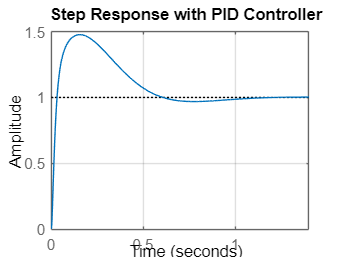

clc;
clear all;
% System matrices (from linearization or given system parameters)
A = [0 1 0; 244.86 -0.094 26.29; 0 0 -250];
B = [0; 0; 5];
C = [1, 0, 0];
D = 0;

[numerator , denumerator] = ss2tf(A, B, C, D);
G = tf(numerator, denumerator);

% Design PID controller
Kp = 1278.8604861075;  % Proportional gain
Ki = 3736.57027457271;  % Integral gain
Kd = 101.778616391159; % Derivative gain
C = pid(Kp, Ki, Kd);

% Closed-loop transfer function
T = feedback(C * G, 1);

% Step response
figure;
step(T);
title('Step Response with PID Controller');
grid on;

Q8)

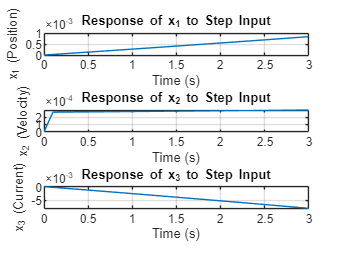

% System matrices (from linearization or given parameters)
A = [0 1 0; 244.86 -0.094 26.29; 0 0 -250];
B = [0;0;5];
C = [1 0 0];
D = 0;

% PID controller parameters (from previous step)
Kp = 1278.8604861075;  % Proportional gain
Ki = 3736.57027457271;  % Integral gain
Kd = 101.778616391159; % Derivative gain
C_pid = pid(Kp, Ki, Kd);

% Convert the system to transfer function
[numerator, denominator] = ss2tf(A, B, C, D);
G = tf(numerator, denominator);

% Closed-loop transfer function
T = feedback(C_pid * G, 1);

% Simulate the state-space system response with the PID controller
sys_cl = ss(A - B * [Kp Ki Kd], B, eye(3), 0); % Closed-loop state-space system

% Time vector
t = 0:0.1:3;

% Step input
u = ones(size(t));

% Response of the state variables
[y, t, x] = lsim(sys_cl, u, t);

% Plot state variable responses
figure;
subplot(3, 1, 1);
plot(t, x(:, 1));
xlabel('Time (s)');
ylabel('x_1 (Position)');
title('Response of x_1 to Step Input');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2));
xlabel('Time (s)');
ylabel('x_2 (Velocity)');
title('Response of x_2 to Step Input');
grid on;

subplot(3, 1, 3);
plot(t, x(:, 3));
xlabel('Time (s)');
ylabel('x_3 (Current)');
title('Response of x_3 to Step Input');
grid on;